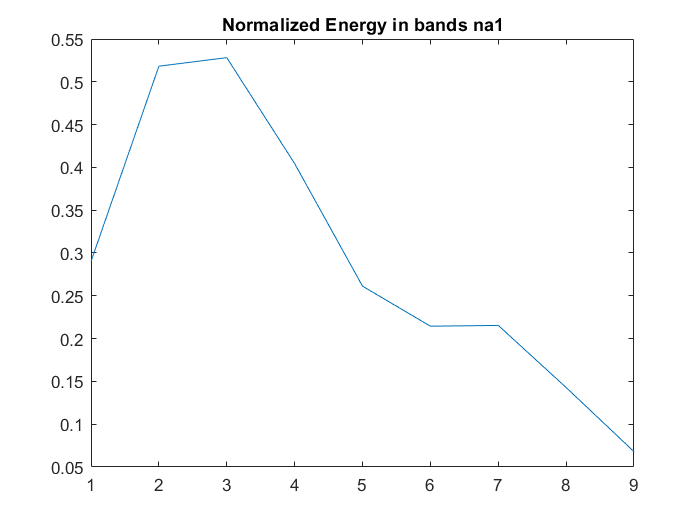

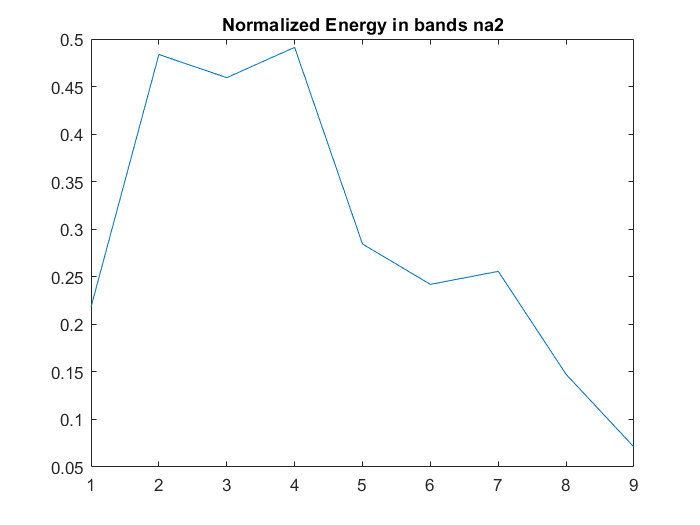

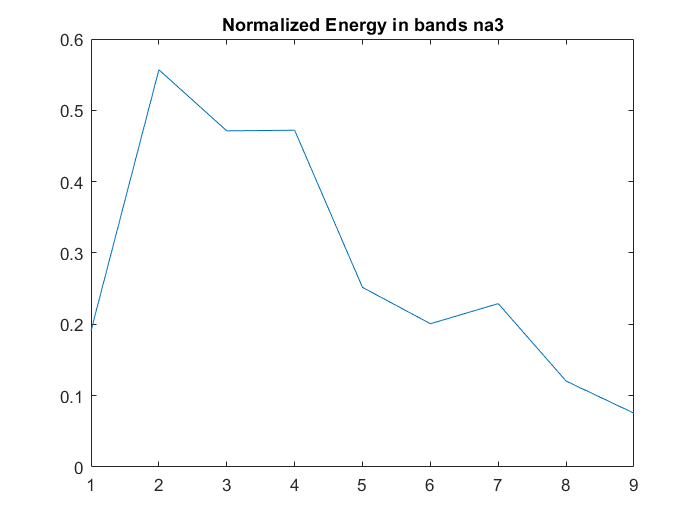

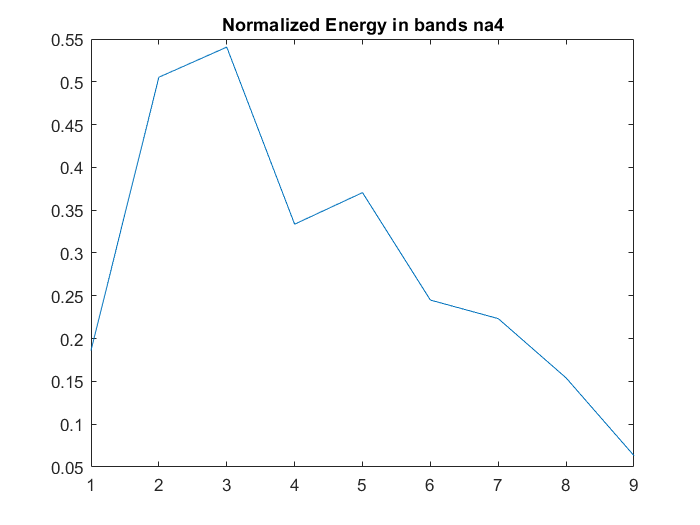

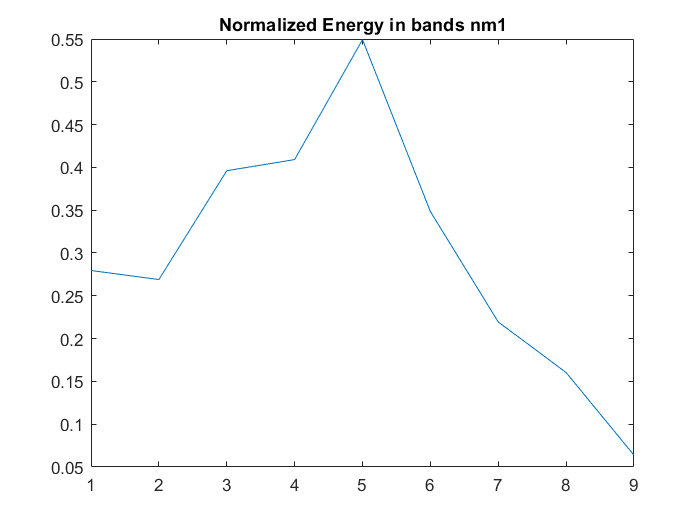

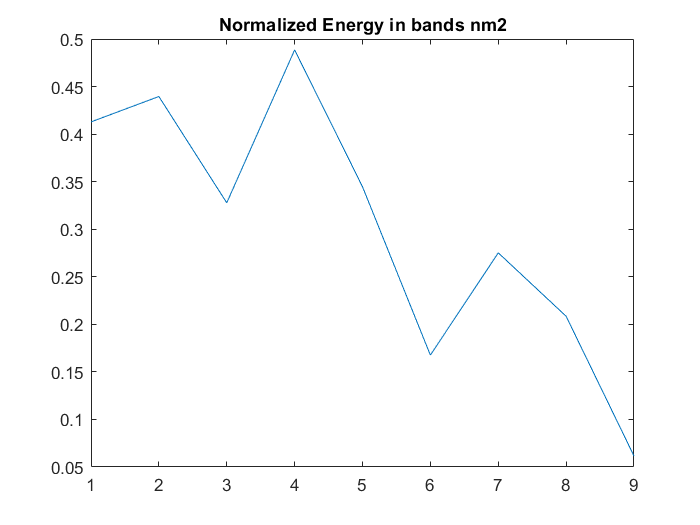

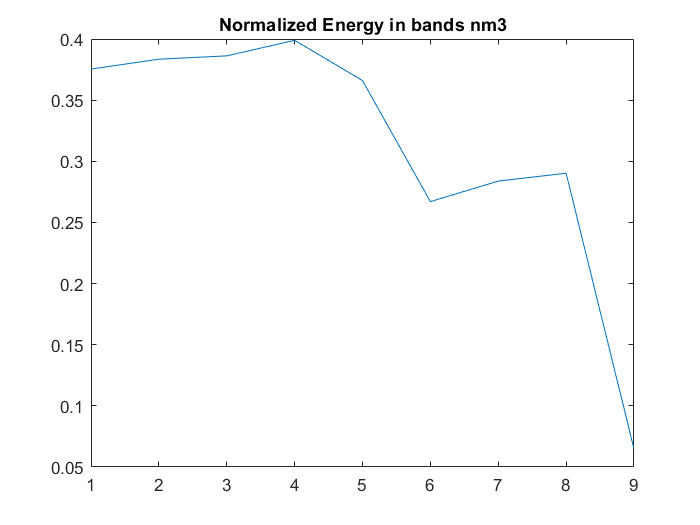

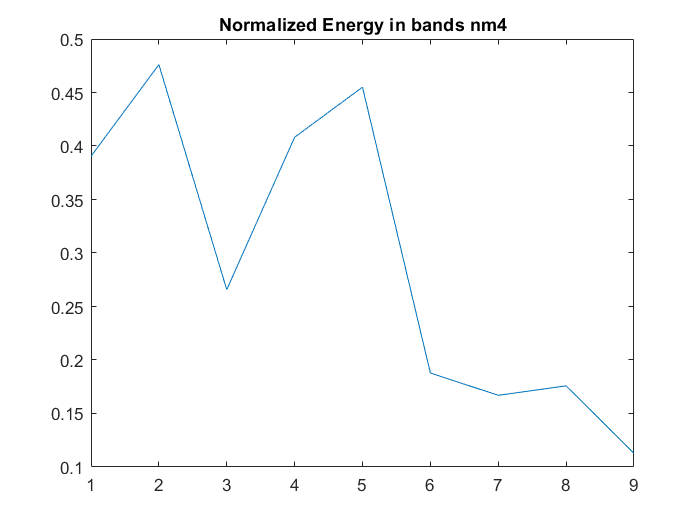

close all;
clear;
numberOfBands = 10;
p = ["n","p","r","s"];
t = ["a","m"];

targetLoudness = -20;

for k = 1:length(p)
    for j = 1:2
        for i=1:4
        filename = "C:\Users\sridh\Documents\MATLAB\DSP\Assignment2\audio\"+ p(k) + t(j) +i+ ".wav";
        [signal,Fs] = getAudio(filename);
        s = preEmphasis(signal);
        [loudness, LRA] = integratedLoudness(s, Fs);
 
        gain = 10^((targetLoudness - loudness)/20);
        s = s.*gain;
        %[loudnessNorm, LRA] = integratedLoudness(signal,Fs)
        
        %plotSignal(s,signal,p(k),t(j),i);
        %fprintf("_______________");
        [filtbank,f,energies] = baapu(s,Fs,numberOfBands);
        energy((j-1)*4+i,:,k) = energies;
        
        figure("Name", "i = " + i + "t = " + t(j));
        plot(energies(1:end-1));
        title("Normalized Energy in bands " + p(k) + t(j) + i);
       

        end
        
    end

end

databank = mean(energy)

databank = databank(:,:,1) =

    0.2929    0.4540    0.4219    0.4258    0.3604    0.2342    0.2336    0.1750    0.0726    0.0910


databank(:,:,2) =

    0.1764    0.6187    0.5077    0.1849    0.3161    0.1759    0.2074    0.1958    0.1390    0.1128


databank(:,:,3) =

    0.1584    0.5267    0.4554    0.3539    0.1441    0.2542    0.3772    0.2199    0.1164    0.0332


databank(:,:,4) =

    0.3132    0.4626    0.3226    0.3884    0.4340    0.2063    0.3285    0.1294    0.1212    0.0716


energy

energy = energy(:,:,1) =

    0.2901    0.5182    0.5282    0.4045    0.2613    0.2145    0.2154    0.1429    0.0679    0.0690
    0.2181    0.4837    0.4594    0.4912    0.2844    0.2420    0.2557    0.1474    0.0710    0.0916
    0.1908    0.5569    0.4713    0.4721    0.2518    0.2008    0.2291    0.1204    0.0754    0.1435
    0.1860    0.5054    0.5406    0.3337    0.3706    0.2450    0.2234    0.1541    0.0633    0.0625
    0.2795    0.2690    0.3961    0.4092    0.5493    0.3485    0.2195    0.1604    0.0638    0.0863
    0.4128    0.4395    0.3278    0.4886    0.3447    0.1676    0.2752    0.2085    0.0615    0.0971
    0.3754    0.3835    0.3862    0.3989    0.3660    0.2670    0.2838    0.2902    0.0648    0.1123
    0.3904    0.4761    0.2658    0.4082    0.4550    0.1878    0.1670    0.1758    0.1128    0.0658


energy(:,:,2) =

    0.1390    0.5550    0.3765    0.2450    0.4882    0.2371    0.2799    0.1955    0.1439    0.1489
    0.1398    0.6034    0.5852    0.2096    0.

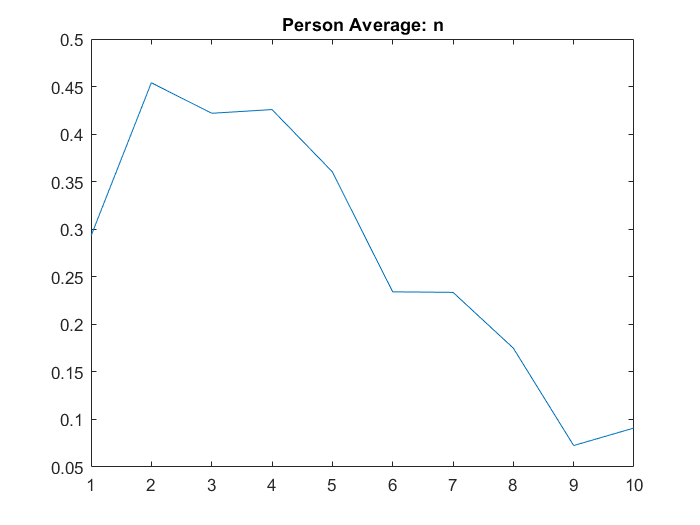

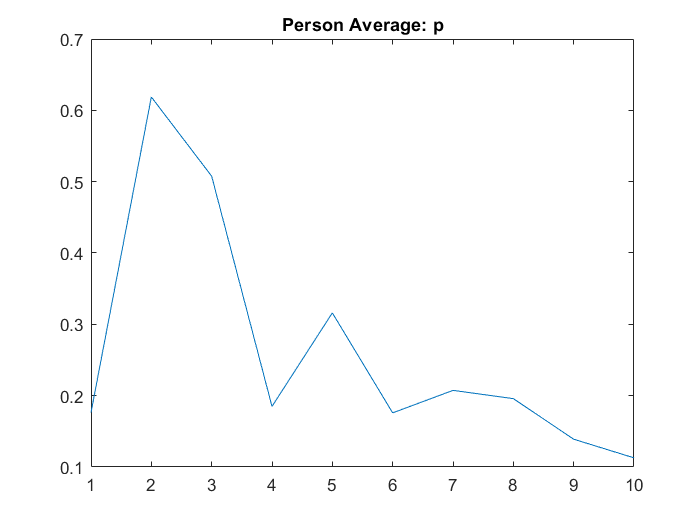

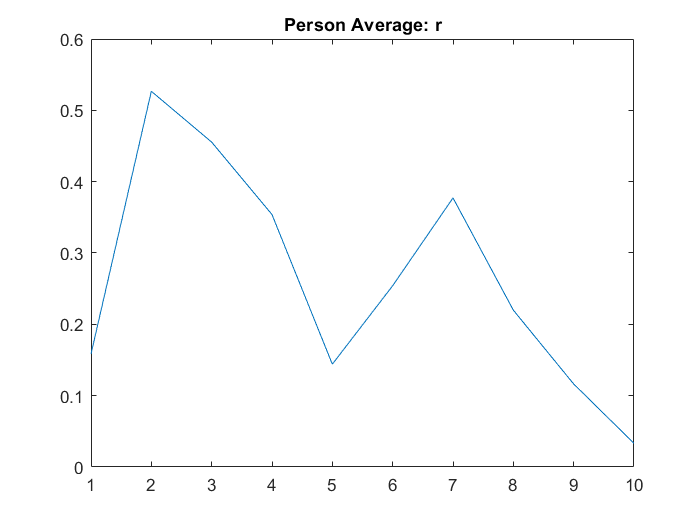

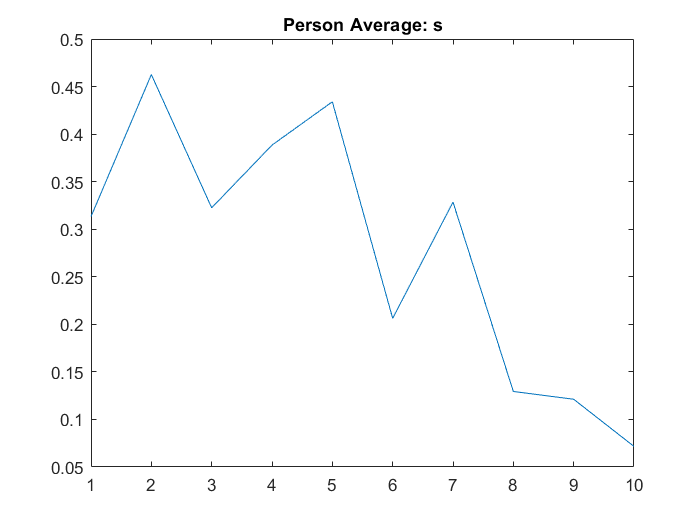

for k = 1:4
    figure("Name","Person " + p(k));
    plot(databank(1,1:end,k));
    title("Person Average: " + p(k));
end

%energy(i,:,k) gives the person. i is the recording number, first 4 are
%afternoon, last 4 are morning. k is the person number, k = 1,2,3,4 ,
%Nivedita, Prerna, Rudrajyoti, Shouvik. 
size(databank);
for i = 1:4
    R = corrcoef(databank(1,:,i),energy(7,:,1))
end

R =     1.0000    0.9158
    0.9158    1.0000


R =     1.0000    0.5679
    0.5679    1.0000


R =     1.0000    0.6387
    0.6387    1.0000


R =     1.0000    0.8308
    0.8308    1.0000



%f = linspace(0,Fs/2-1,numberOfBands+1)

f = 	1.0e+03 *

         0    0.3999    0.7998    1.1997    1.5996    1.9995    2.3994    2.7993    3.1992    3.5991    3.9990


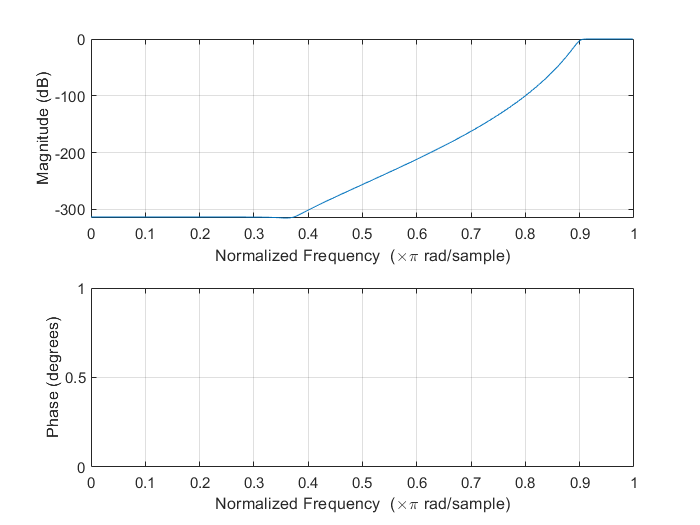

%i = length(f)-1;
%g = [f(i),f(i+1)];
%sos = genfilter(Fs,g);
%freqz(sos);

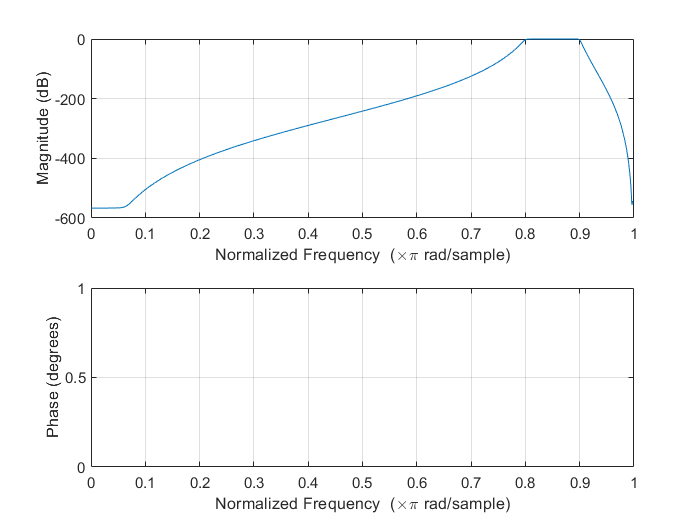


%i = i-1;
%g = [f(i),f(i+1)];
%sos = genfilter(Fs,g);
%freqz(sos);

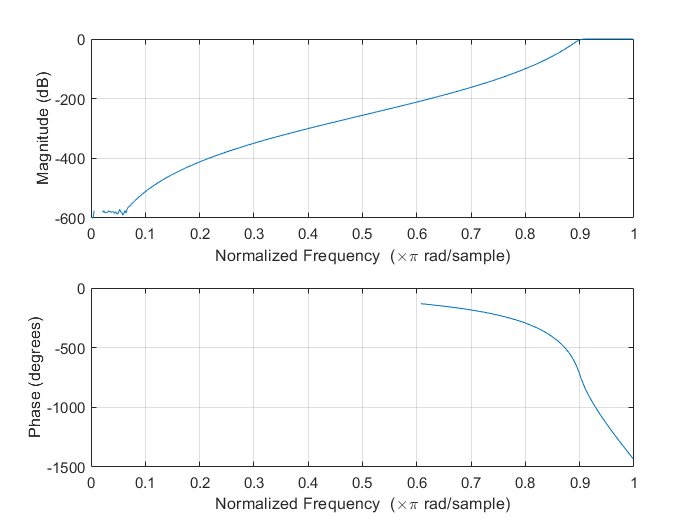


%[b,a] = butter(16,2*f(end-1)/Fs,'high');
%freqz(b,a);


%energy


%t = (0:(length(signal)-1))/Fs;
%plot(t,signal); xlabel("Time(s)"); ylabel("Amplitude"); title("Audio");

%t = (0:(length(signal)-1))/Fs;
%fsignal = noisefilt(signal,Fs);
%plot(t,fsignal); xlabel("Time(s)"); ylabel("Amplitude"); title("Filtered Audio");
%env2 = hilbert(fsignal);
%plot(abs(env2));

%[yf,yfft] = FFT(signal,length(signal),Fs);
%plot(yf,20*log(abs(yfft)));
%xlabel("Frequency"); ylabel("Amplitude (dB)"); title("Unfilteres FFT");

%env = hilbert(signal);
%plot(abs(env));


%[filtbank,f] = banks(signal,Fs,numberOfBands);

%energies = powers(filtbank,signal)






function [x,Fs] = getAudio(name)
Fs = 6000;  %Sampling ratio given
[audio,fs] = audioread(name);
downratio = floor(fs/Fs);
Fs = fs/downratio;  %Might not be exact required frequency
x = downsample(audio,downratio);
end

function [sos] = genfilter(Fs, f)
    [A, B, C, D] = butter(16,[f(1) f(2)]/(Fs/2));    %%Normalized frequency has to be supplied
    sos = ss2sos(A,B,C,D);    %%Convert state space matrix to something usable 
end


function [filtbank,f] = banks(x,Fs, k)
    f = linspace(0,Fs/2-1,k+1);
    %LPF
    %[A,B,C,D] = butter(8,2*f(1)/Fs);
    %sos=ss2sos(A,B,C,D);
    [b,a] = butter(16,2*f(2)/Fs);
    filtbank(1,:) = filtfilt(b,a,x);
    [b,a] = butter(16,2*f(end-1)/Fs,'high');
    filtbank(length(f)-1,:) = filtfilt(b,a,x);
    %Using a bandpass signal used to bloat up value of the last filter
    %somehow, probably due to aliasing in the filter?
    for i = 2:(length(f)-2)
        g = [f(i),f(i+1)];
        sos = genfilter(Fs,g);
        filtbank(i,:) = filtfilt(sos,1,x);
    end
end

function [y] = noisefilt(x,Fs)
n = 0.15*Fs;
%if shouvik's file, increase this length
nmean = mean(abs(x(1:n)));
for i = 1:(length(x))
    if(abs(x(i))<5*nmean)
        y(i) = 0;
    else
        y(i) = x(i);
    end
end
end

function [f,DFFT] = FFT(xt,N,Fs)
DFFT2 = fft(xt,N)/N;
DFFT = fftshift(DFFT2);
f = Fs/length(DFFT)*linspace(-length(DFFT)/2,length(DFFT)/2-1,N);
end

function [y] = powers(x,xorig)
    dim = size(x);
    for i=1:dim(1)
        y(i) = norm(x(i,:));
    end
    porig = norm(xorig);
    y = y/porig;
    %y = y/sum(y);
end

function [] = frequencydomain(filtbank,Fs,numberOfBands)
for i=1:numberOfBands
    [yf,yfft] = FFT(filtbank(i,:),length(filtbank(i,:)),Fs);
    figure("name","i");
    plot(yf,20*log(abs(yfft)));
    xlabel("Frequency"); ylabel("Amplitude (dB)"); title("Filtered FFT f1 = "+ f(i) + " f2 = "+f(i+1));
    xlim([-4000 4000]);
end
end

function [filtbank,f,energies] = baapu(signal,Fs,numberOfBands)
[filtbank,f] = banks(signal,Fs,numberOfBands);
energies = powers(filtbank,signal);
end

function [y] = preEmphasis(x)
    h = [1 -0.95];
    y = filter(h,1,x);
end

function plotFFT(s,signal,Fs)
    figure("Name","FFT");
    [yf,yfft] = FFT(signal,length(signal),Fs);
    [yff,yfftf] = FFT(s,length(s),Fs);
    subplot(211);
    plot(yf,20*log(abs(yfft)));
    xlabel("Frequency"); ylabel("Amplitude (dB)"); title("UnFiltered FFT");
    subplot(212);
    plot(yff,20*log(abs(yfftf)));
    xlabel("Frequency"); ylabel("Amplitude (dB)"); title("Filtered FFT");
end

function plotSignal(s,signal,p,t,i)
        figure("Name","Time domain Signal" + p + t + i);
        subplot(211);
        plot(signal); title("Time domain unfiltered" + p + t + i);
        subplot(212);
        plot(s); title("Time domain filtered" + p + t + i);
end